# **IMAGE OPERATIONS**

### ADDITION

close all; clear all; clc;
A = imread("cameraman.tif")

A = 256×256 uint8 matrix
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156

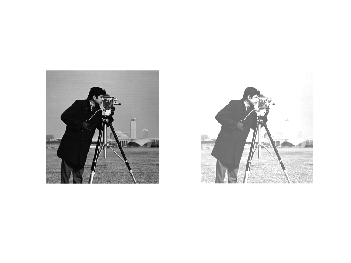

subplot(1,2,1), imshow(A);
B = imadd(A,100); %%Add 100 to each pixel
%%B = A +100; SIMPLE
subplot(1,2,2), imshow(B);

### SUBSTRACTION

A1 = imread("AT3_1m4_01.tif");
B1 = imread("AT3_1m4_01.tif");
figure;
subplot(1,3,1), imshow(A1);
subplot(1,3,2), imshow(B1);
Output = imsubtract(A1,B1); %%SUBSTRACT
%%Output = A1-B1;
subplot(1,3,3),imshow(Output);

### DIFF ABS

Output = imabsdiff(A1,B1);
subplot(1,3,3), imshow(Output);

### MULTIPLICATION

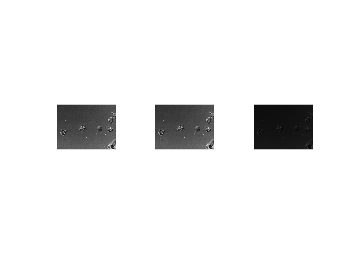

Output = immultiply(A1,1.5);
subplot(1,3,3),imshow(Output);
Output = imdivide(A1,4);
subplot(1,3,3),imshow(Output);

### COMPLEMENT VALUE

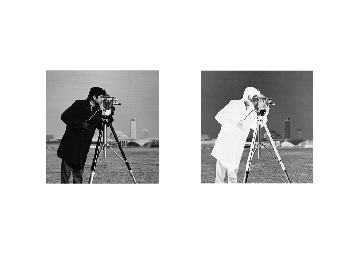

figure;
A2 = imread("cameraman.tif");
subplot(1,2,1),imshow(A2);
B2 = imcomplement(A2);
subplot(1,2,2),imshow(B2);

### RICE BIN

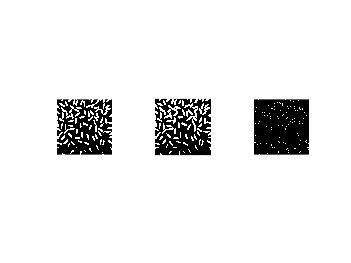

figure;
A3 = imread("rice.png");
B3 = imread("riceblurred.png");
Abw = imbinarize(A3);
Bbw = imbinarize(B3); %%Binarización por clase según los bins
subplot(1,3,1), imshow(Abw);
subplot(1,3,2), imshow(Bbw);
OutputR = xor(Abw,Bbw);
subplot(1,3,3), imshow(OutputR);

### BOOLEAN/LOGICAL

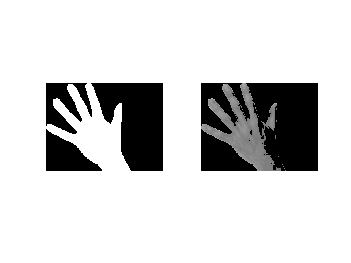

figure;
A4 = imread("hands1.jpg");
A4 = rgb2gray(A4);
B4 = imread("hands1-mask.png");
figure;
subplot(1,2,1);
imshow(B4);

A4(~B4)=0; %% Asigna 0 a los elementos de A4 donde B4 es false

A4(A4<120)=0; %% Asigna 0 a los elementos de A4 que sean menores a 120

subplot(1,2,2);

imshow(A4);

### HISTOGRAM

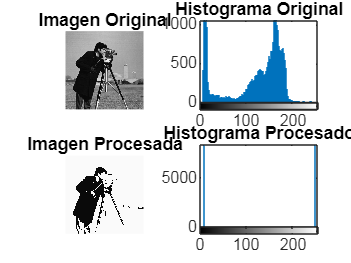

figure;
A5 = imread("cameraman.tif");

subplot(2,2,1);
imshow(A5);
title("Imagen Original");

subplot(2,2,2);
imhist(A5);
title("Histograma Original");

A5(A5 <= 30) = 10;
A5(A5 > 30) = 250; 

subplot(2,2,3);
imshow(A5);
title("Imagen Procesada");

subplot(2,2,4);
histogram
imhist(A5);
title("Histograma Procesado");

### LOG/EXP

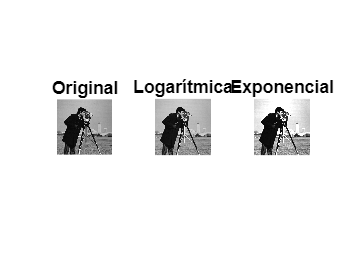

A6 = imread("cameraman.tif"); 
A6 = im2double(A6);

c_log = 1 / log(1 + max(A6(:))); % Factor de escala para la transformación logarítmica
log_transform = c_log * log(1 + A6); % Aplicación de la transformación logarítmica
c_exp = 1; % Factor de escala para la transformación exponencial
exp_transform = c_exp * (exp(A6) - 1); % Aplicación de la transformación exponencial

figure;
subplot(1,3,1);
imshow(A6);
title("Original");
subplot(1,3,2);
imshow(log_transform);
title("Logarítmica");
subplot(1,3,3);
imshow(exp_transform);
title("Exponencial");